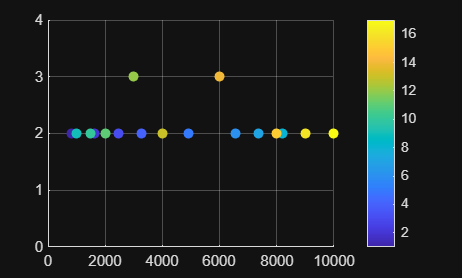


% Parameters

fs = 44100;
blockLength=4096;

fRatio = 1.22;

f2aim = [500:500:1500 2000:1000:10000].';

% FFT bin frequencies
freqFFT=(0:blockLength/2-1).'*fs/blockLength;

% Finds the equivalent FFT bin for a given f2 and f1 frequencies
idxFreq=round((f2aim*blockLength/fs+1).*[1/fRatio 1]);
% adds a columns for the DP position given 2f1-f2
idxFreq(:,3)=2*idxFreq(:,1)-idxFreq(:,2);

%Reshapes to Nx3
freq=reshape(freqFFT(idxFreq),size(idxFreq));


fAim = f2aim.*[1/fRatio 1];
fAim(:,3) = 2*fAim(:,1)-fAim(:,2);
dpAim = calcDPVector(fAim);
totalAim = [fAim, dpAim];


%looks for overlap
[dupes, dupeLoc] = findDupes(totalAim);
n = length(dupes);

dupePairs = zeros(2, n/2);
dupePairs(2,:) = 1;
dupeLocPairs = zeros(2, n/2);
for k = 1:n/2
    for l = k+1:n
        if dupes(k) == dupes(l)
            dupePairs(1,k) = dupes(k);
            dupePairs(2,k) = dupePairs(2,k)+1;

            dupeLocPairs(1, k) = dupeLoc(k);
            dupeLocPairs(2, k) = dupeLoc(l);
        end
    end
end

dupePairs(:,any(dupePairs == 0))=[];
m = length(dupePairs(1,:));


%%%%% PLOT %%%%%
c = linspace(1,m,m);
scatter(dupePairs(1,:), dupePairs(2,:), [], c, "filled")
% stem(dupePairs(1,:), dupePairs(2,:), 'LineStyle', '-', 'Marker', 'o')
axis([0 1e4 0 4])
grid on
colorbar

%%% PLOT END %%%

function [dpVector] = calcDPVector(freq)
dpVector = [freq(:,2)-freq(:,1), 2*freq(:,2)-freq(:,1), 2*freq(:,1), freq(:,1)+freq(:,2), 2*freq(:,2), 3*freq(:,1), 2*freq(:,1)+freq(:,2), freq(:,1)+2*freq(:,2), 3*freq(:,2)];
end

function [dupes, dupeLoc] = findDupes(A)
[~, uniqueIdx] = unique(A);
dupeIdx = ismember( A, A( setdiff( 1:numel(A), uniqueIdx ) ) );
dupes = A(dupeIdx);
dupeLoc = find(dupeIdx);
end